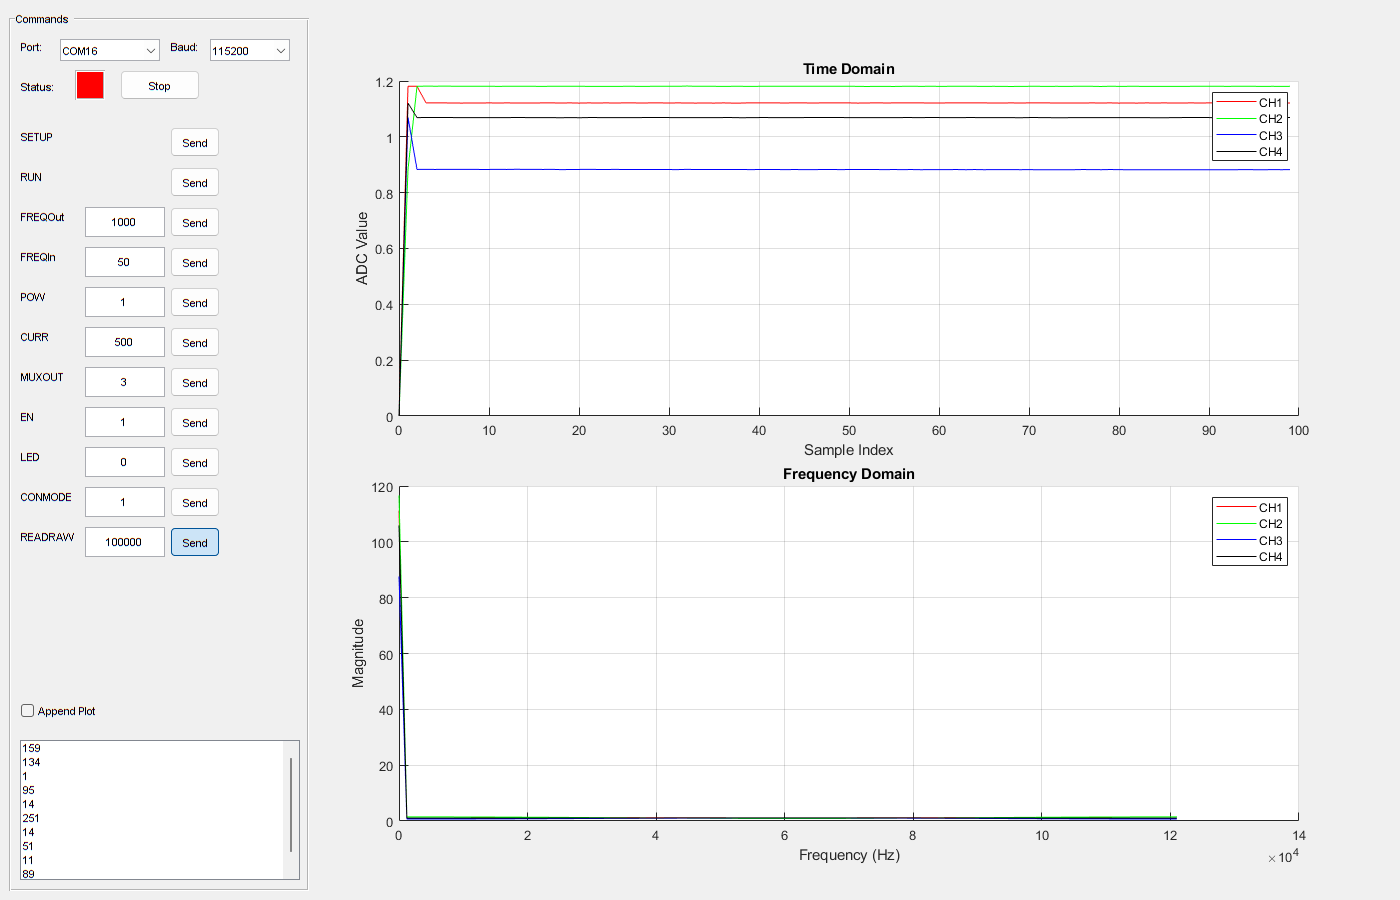

load("testy_03_03_25_biuro.mat");

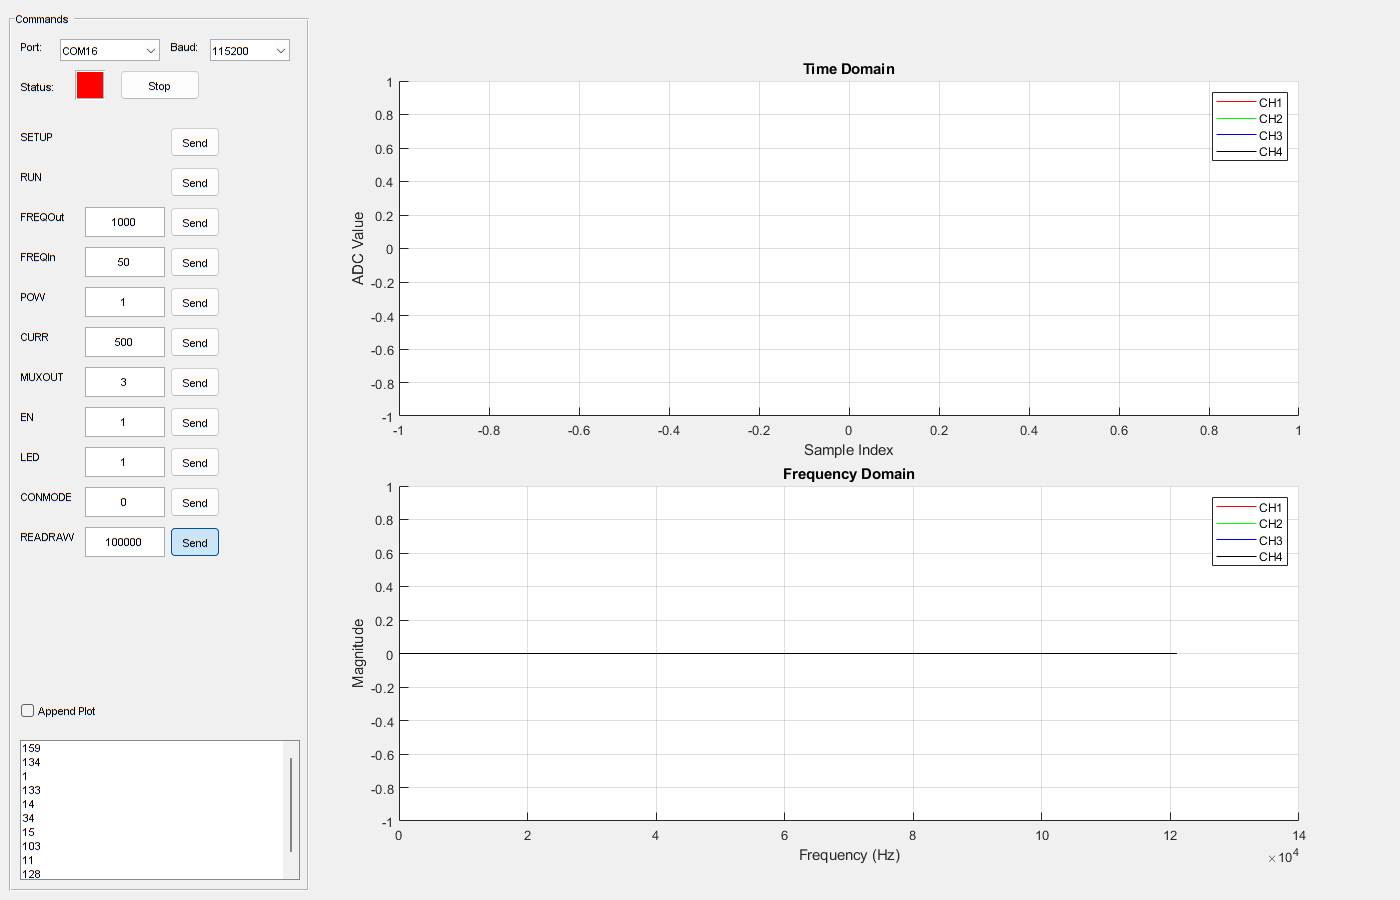

load("testy_04_03_25_biuro.mat");

load("testy_10_03_25_biuro_ref.mat", 'ch1', 'ch2', 'ch3', 'ch4', 'sampleIndex');

load("testy_10_03_25_biuro_bpm55.mat", 'ch1', 'ch2', 'ch3', 'ch4', 'sampleIndex');

load("lab_12_03_test1.mat")

load("testy_18_03_25_biuro_reka2.mat", 'ch1', 'ch2', 'ch3', 'ch4', 'sampleIndex');

load("testy_23_03_25_dom_reka_stalaczest.mat", 'ch1', 'ch2', 'ch3', 'ch4', 'sampleIndex');

function I = radar_echo2(ch1, ch2, ch3, ch4)
    P4 = (vpa(ch3,3) - 14970.8) / 369.597;
    P3 = (vpa(ch2,3) - 14970.8) / 369.597;
    P2 = (vpa(ch1,3) - 14970.8) / 369.597;
    Pref = (vpa(ch4,3) - 14970.8) / 369.597;
    P4norm = P4-Pref;
    P3norm = P3-Pref;
    P2norm = P2-Pref;
    P4norm = 10.^(P4norm/10);
    P3norm = 10.^(P3norm/10);
    P2norm = 10.^(P2norm/10);
    I = -P2norm+0.5*P3norm+0.5*P4norm+1i*sqrt(3)/2*(-P3norm+P4norm);
end

function I = radar_echo(ch1, ch2, ch3, ch4)
    P4 = (ch3 - 14970.8) / 369.597;
    P3 = (ch2 - 14970.8) / 369.597;
    P2 = (ch1 - 14970.8) / 369.597;
    Pref = (ch4 - 14970.8) / 369.597;
    P4norm = P4-Pref;
    P3norm = P3-Pref;
    P2norm = P2-Pref;
    P4norm = 10.^(P4norm/10);
    P3norm = 10.^(P3norm/10);
    P2norm = 10.^(P2norm/10);
    I = -P2norm+0.5*P3norm+0.5*P4norm+1i*sqrt(3)/2*(-P3norm+P4norm);
end

radar_echo(49,49,49,49)

ans = 0

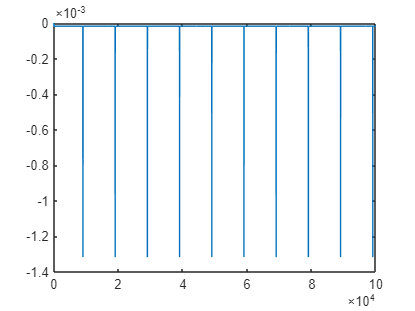

plot(sampleIndex, I);

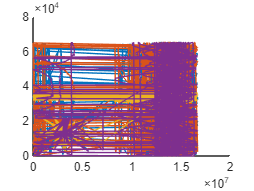

figure(1); clf; hold on;
plot(sampleIndex, ch1);
plot(sampleIndex, ch2);
plot(sampleIndex, ch3);
plot(sampleIndex, ch4);

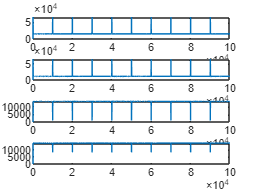

figure(6); clf; hold on;
subplot(4,1,1); plot(ch1);
subplot(4,1,2); plot(ch2);
subplot(4,1,3); plot(ch3);
subplot(4,1,4); plot(ch4);

ch1_filtered = ch1;
ch2_filtered = ch2;
ch3_filtered = ch3;
ch4_filtered = ch4;

for i = find(ch1 == max(ch1))
    disp(ch1_filtered(i));
    disp(ch1_filtered(i-1));
    ch1_filtered(i) = ch1_filtered(i-1);
    ch2_filtered(i) = ch2_filtered(i-1);
    ch3_filtered(i) = ch3_filtered(i-1);
    ch4_filtered(i) = ch4_filtered(i-1);
    disp(ch1_filtered(i));
    disp(ch1_filtered(i-1));
    disp(i);
end

       65532



     0



     0



     0



     2



       65532



       15233



       15233



       15233



       10002



       65532



       15256



       15256



       15256



       20002



       65532



       15249



       15249



       15249



       30002



       65532



       15254



       15254



       15254



       40002



       65532



       15260



       15260



       15260



       50002



       65532



       15277



       15277



       15277



       60002



       65532



       15258



       15258



       15258



       70002



       65532



       15258



       15258



       15258



       80002



       65532



       15222



       15222



       15222



       90002



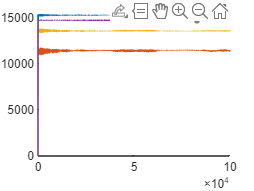

figure(1); clf; hold on;
plot(sampleIndex, ch1_filtered);
plot(sampleIndex, ch2_filtered);
plot(sampleIndex, ch3_filtered);
plot(sampleIndex, ch4_filtered);

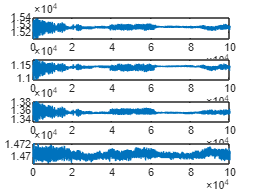

figure(7); clf; hold on;
subplot(4,1,1); plot(ch1_filtered(3:end));
subplot(4,1,2); plot(ch2_filtered(3:end));
subplot(4,1,3); plot(ch3_filtered(3:end));
subplot(4,1,4); plot(ch4_filtered(3:end));

%%% CALCULATING RADAR ECHO

%BPM55 VALUES
ch1_filtered_bpm55 = ch1;
ch2_filtered_bpm55 = ch2;
ch3_filtered_bpm55 = ch3;
ch4_filtered_bpm55 = ch4;
I_bpm55 = radar_echo(ch1_filtered_bpm55, ch2_filtered_bpm55, ch3_filtered_bpm55, ch4_filtered_bpm55)

%REF VALUES
ch1_filtered_ref = ch1_filtered;
ch2_filtered_ref = ch2_filtered;
ch3_filtered_ref = ch3_filtered;
ch4_filtered_ref = ch4_filtered;
I_ref = radar_echo(ch1_filtered_ref, ch2_filtered_ref, ch3_filtered_ref, ch4_filtered_ref)

I_ref =    0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0899 + 0.3443i  -1.0905 + 0.3442i  -1.0901 + 0.3446i  -1.0947 + 0.3452i  -1.0942 + 0.3447i  -1.0934 + 0.3456i  -1.0959 + 0.3467i  -1.0970 + 0.3459i  -1.0979 + 0.3466i  -1.0990 + 0.3458i  -1.1025 + 0.3465i  -1.1030 + 0.3465i  -1.1045 + 0.3459i  -1.1050 + 0.3459i  -1.1101 + 0.3454i  -1.1096 + 0.3440i  -1.1113 + 0.3445i  -1.1125 + 0.3433i  -1.1123 + 0.3424i  -1.1147 + 0.3419i  -1.1183 + 0.3408i  -1.1198 + 0.3397i  -1.1226 + 0.3389i  -1.1193 + 0.3377i  -1.1224 + 0.3369i  -1.1238 + 0.3354i  -1.1239 + 0.3340i  -1.1224 + 0.3328i  -1.1264 + 0.3324i  -1.1277 + 0.3304i  -1.1240 + 0.3286i  -1.1268 + 0.3270i  -1.1277 + 0.3259i  -1.1273 + 0.3241i  -1.1270 + 0.3219i  -1.1263 + 0.3206i  -1.1313 + 0.3193i  -1.1295 + 0.3170i  -1.1310 + 0.3153i  -1.1306 + 0.3146i  -1.1286 + 0.3127i  -1.1293 + 0.3113i  -1.1275 + 0.3091i  -1.1284 + 0.3086i  -1.1277 + 0.3062i  -1.1264 + 0.3050i  -1.1250 + 0.3041i  -1.1258 + 0.3023i


I_final = I_bpm55 - I_ref;

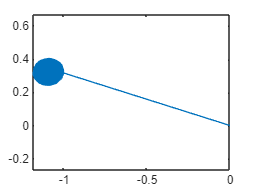

figure(5); clf; 
plot(real(I_ref), imag(I_ref));
axis Equal;

ch1_movedto0 = ch1_filtered(2:end) - ones(size(ch1_filtered(2:end)))*mean(ch1_filtered(2:end));
ch2_movedto0 = ch2_filtered(2:end) - ones(size(ch2_filtered(2:end)))*mean(ch2_filtered(2:end));
ch3_movedto0 = ch3_filtered(2:end) - ones(size(ch3_filtered(2:end)))*mean(ch3_filtered(2:end));
ch4_movedto0 = ch4_filtered(2:end) - ones(size(ch4_filtered(2:end)))*mean(ch4_filtered(2:end));
sampleIndex_moveto0 = sampleIndex(2:end);

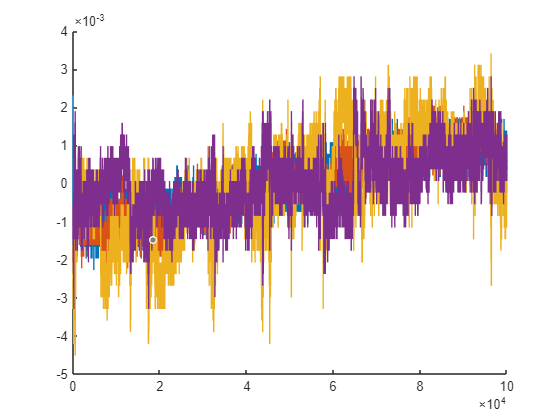

figure(2); clf; hold on;
plot(sampleIndex_moveto0, ch1_movedto0);
plot(sampleIndex_moveto0, ch2_movedto0);
plot(sampleIndex_moveto0, ch3_movedto0);
plot(sampleIndex_moveto0, ch4_movedto0);

fsampling = 1000;
fch1_clean = fft(ch1);
%fch1_clean = [fch1_clean((length(fch1_clean)-1)/2:end), fch1_clean(1:(length(fch1_clean)-1)/2)];
fch2_clean = fft(ch2);
%fch2_clean = [fch2_clean((length(fch2_clean)-1)/2:end), fch2_clean(1:(length(fch2_clean)-1)/2)];
fch3_clean = fft(ch3);
%fch3_clean = [fch3_clean((length(fch3_clean)-1)/2:end), fch3_clean(1:(length(fch3_clean)-1)/2)];
fch4_clean = fft(ch4);
%fch4_clean = [fch4_clean((length(fch4_clean)-1)/2:end), fch4_clean(1:(length(fch4_clean)-1)/2)];
fch5_clean = fft(radar_echo(ch1, ch2, ch3, ch4));

%f = linspace(-fsampling/2, fsampling/2, length(fch1_clean));
f = linspace(0, fsampling, length(fch1_clean));

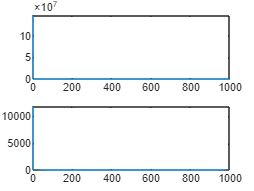

figure(3); clf; hold on;
subplot(2,1,1);
plot(f, abs(fch1_clean));
plot(f, abs(fch2_clean));
plot(f, abs(fch3_clean));
plot(f, abs(fch4_clean));
subplot(2,1,2);
plot(f, abs(fch5_clean));

fft_clean = abs(fch1_clean) + abs(fch2_clean) + abs(fch3_clean) + abs(fch4_clean);

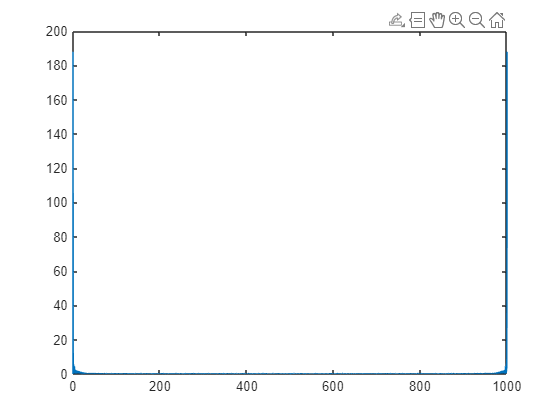

figure(4); clf; 
plot(f, fft_clean);